## Load Data ex 2: house prices estimation

clc
clear
close all

data = load('Data/ex1data2.txt');
X = data(:, 1:2); % regressors matrix
y = data(:, 3); % output
N = length(y); % number of training samples \ observations

% Print out some data points
fprintf('First 10 examples from the dataset: \n');

First 10 examples from the dataset: 


fprintf(' x = [%.0f %.0f], y = %.0f \n', [X(1:10,:) y(1:10,:)]');

 x = [2104 3], y = 399900 
 x = [1600 3], y = 329900 
 x = [2400 3], y = 369000 
 x = [1416 2], y = 232000 
 x = [3000 4], y = 539900 
 x = [1985 4], y = 299900 
 x = [1534 3], y = 314900 
 x = [1427 3], y = 198999 
 x = [1380 3], y = 212000 
 x = [1494 3], y = 242500 


## Least squares - normal equations

% ====================== YOUR CODE HERE ===================================
% Instructions: Compute the estimate for linear regression using normal equations

% You need to estimate the following variables correctly

X = [X,ones(length(X),1)]

X =         2104           3           1
        1600           3           1
        2400           3           1
        1416           2           1
        3000           4           1
        1985           4           1
        1534           3           1
        1427           3           1
        1380           3           1
        1494           3           1


theta_hat = inv((X.'*X))*(X.'*y) % insert here the code, instead of " = 0";

theta_hat = 1.0e+04 *

    0.0139
   -0.8738
    8.9598



% =========================================================================


% Display normal equation's result
fprintf('Theta computed from the normal equations: \n');

Theta computed from the normal equations: 


fprintf(' %f \n', theta_hat);

 139.210674 
 -8738.019112 
 89597.909543 


fprintf('\n');


% Estimate the price of a 1650 sq-ft, 3 br house
price_hat = [1650 3 1 ]*theta_hat;

fprintf(['Predicted price of a 1650 sq-ft, 3 br house ' ...
    '(using normal equations):\n $%f\n'], price_hat);

Predicted price of a 1650 sq-ft, 3 br house (using normal equations):
 $293081.464335


fprintf('\n');
fprintf('\n');


## fitlm prova

X = data(:, 1:2); % Regressors matrix
mdl = fitlm(X,y).Coefficients.Estimate

mdl = 1.0e+04 *

    8.9598
    0.0139
   -0.8738


[1 1650 3 ]*mdl

ans = 2.9308e+05

## Gradient Descent

% Scale features and set them to zero mean
fprintf('Normalizing Features ...\n');

Normalizing Features ...



[Z mu sigma] = featureNormalize(X); % normalize data

% Add intercept term to normalized data matrix Z
Xaug = [ones(N, 1) Z];

fprintf('Running gradient descent ...\n');

Running gradient descent ...



% Choose some alpha value
alpha = 0.01;
num_iters = 500;

% Init Theta and Run Gradient Descent
theta_hat = zeros(3, 1)

theta_hat =      0
     0
     0


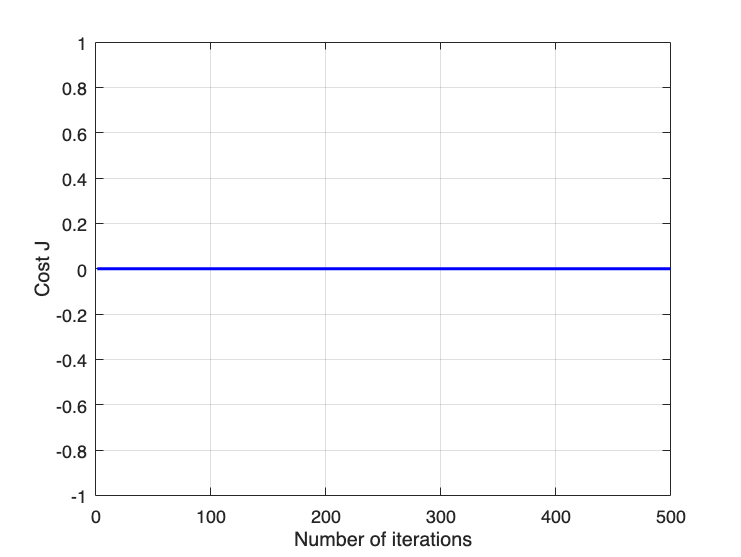

[theta_hat, J_history] = gradientDescentMulti(Xaug, y, theta_hat, alpha, num_iters);
% Plot the convergence graph
figure;
plot(1:numel(J_history), J_history, '-b', 'LineWidth', 2);
xlabel('Number of iterations');
ylabel('Cost J'); grid on;


% Display gradient descent's result
fprintf('Theta computed from gradient descent: \n');

Theta computed from gradient descent: 


fprintf(' %f \n', theta_hat);

 NaN 
 NaN 
 NaN 


fprintf('\n');

% Estimate the price of a 1650 sq-ft, 3 br house
% Recall that the first column of X is all-ones. Thus, it does
% not need to be normalized.

z = ([1650 3] - mu)./sigma; % now you should work with normalized data
z = [1 z]; % add dummy regressor for intercept term to normalized data
price_hat = z*theta_hat ;  % estimated price

% ============================================================

fprintf(['Predicted price of a 1650 sq-ft, 3 br house ' ...
    '(using gradient descent):\n $%f\n'], price_hat);

Predicted price of a 1650 sq-ft, 3 br house (using gradient descent):
 $NaN


## Funzione già fatta

result = gradientDescent(X, y, alpha, num_iters, 5)

result = 1.0e+50 *

    3.4840    3.4842
    0.0050    0.0050
